# Exercici 3 de Laboratori

## **Exercici 1.**

La lògica ens diu que derivar una imatge i després integrar-la ens deixaria la imatge original inalterada. Comproveu si és així al utilitzar dues finestres de convolució, una de derivativa i un altre integrativa.

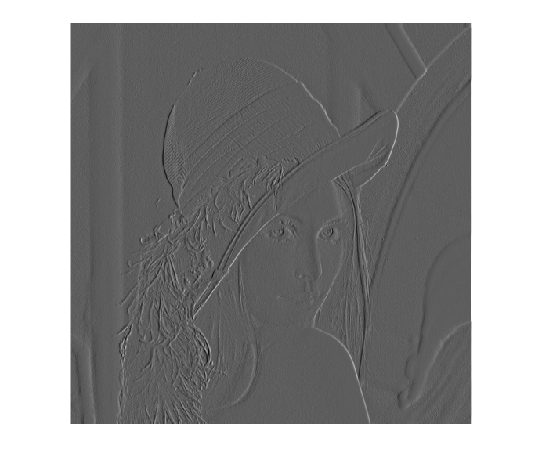

I = imread('lena_gray_512.tif');
% filtre derivatiu
hd = [1 -1];
L = imfilter(double(I), hd);
imshow(L, []);

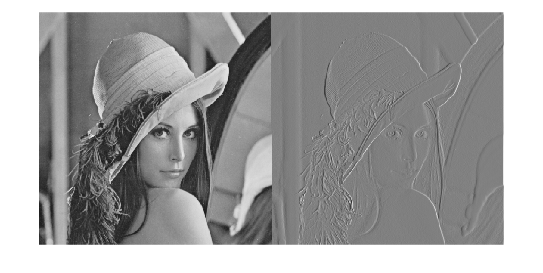

% filtre integratiu
hi = [1 1];
hi = hi/sum(hi, 'all');
G = imfilter(L, hi);
G = uint8(G + 128);
montage({I, G});

## Exercici 2.

Enaltiu (*contour enhancement*) els contorns d’una imatge RGB. El resultat haurà de ser una imatge en nivells de gris combinant els tres canals.

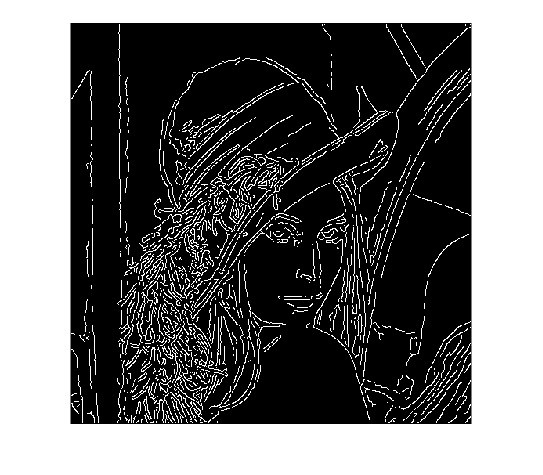

I = imread('lena_color_512.tif');
% canal vermell
R = edge(I(:,:,1), "canny");
imshow(R);

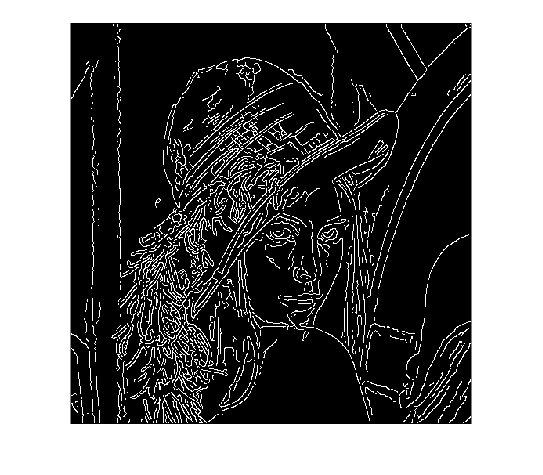

% canal verd
G = edge(I(:,:,2), "canny");
imshow(G);

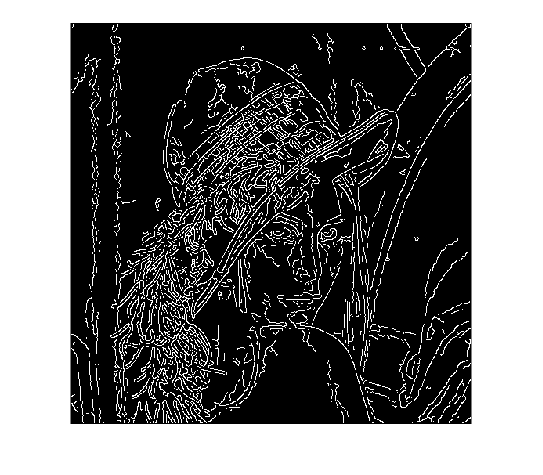

% canal blau
B = edge(I(:,:,3), "canny");
imshow(B);

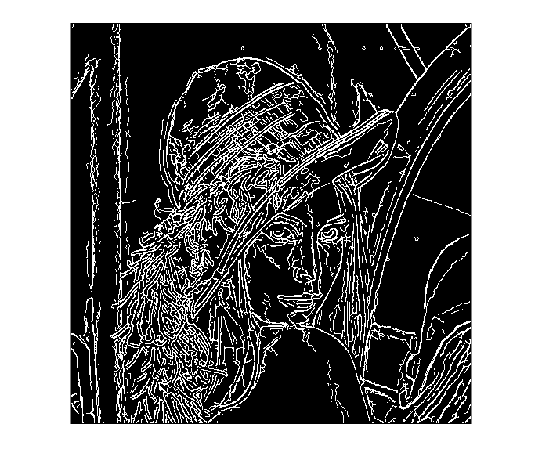

% suma de contorns
J = R + G + B;
imshow(J);

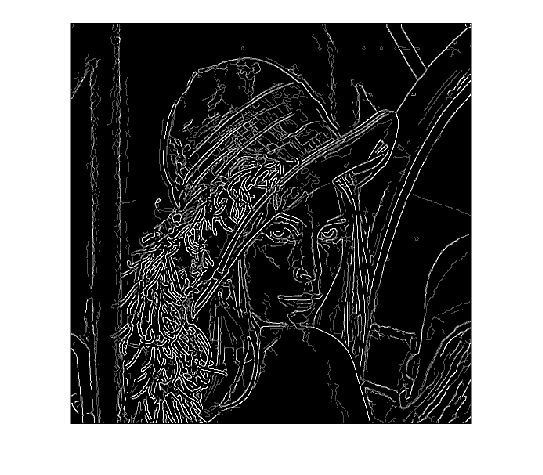

% "average" dels contorns
imshow(J, []);

## Exercici 3.

Quant una part de la imatge està desenfocada presenta els contorns borrosos o suavitzats. En base a aquest fet, fer una funció que mesuri un possible valor l’enfoc en la part central d’una imatge. Així una imatge que  estigui més ben enfocada que un altre tindrà un valor superior. Proveu amb dues imatges extretes d’internet (cerqueu les paraules clau  *focus stacking*)

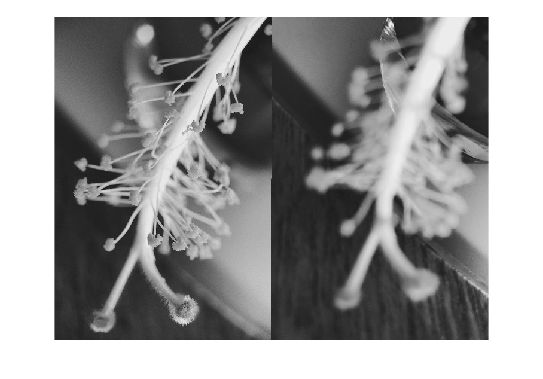

F1 = rgb2gray(imread('Image2.png'));
F2 = rgb2gray(imread('Image1.png'));
montage({F1, F2});

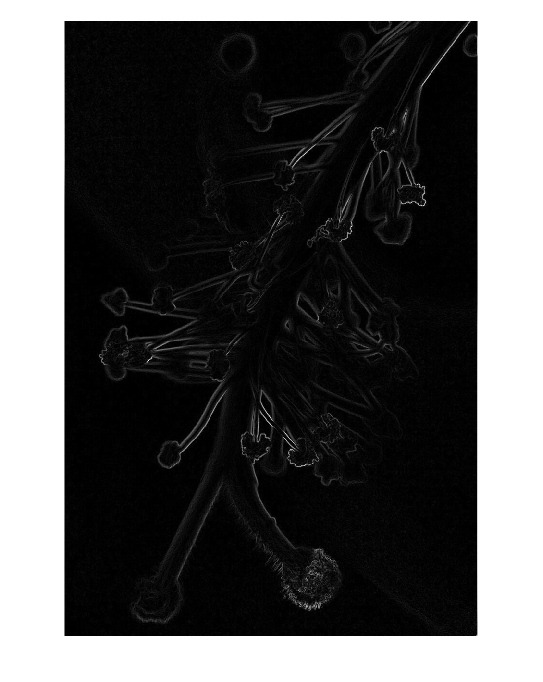

% imatge enfocada
hx = [1 0 -1; 2 0 -2; 1 0 -1];
Gx = imfilter(double(F1), hx);
hy = hx';
Gy = imfilter(double(F1), hy);
Modul = abs(Gx) + abs(Gy);
imshow(Modul,[]);

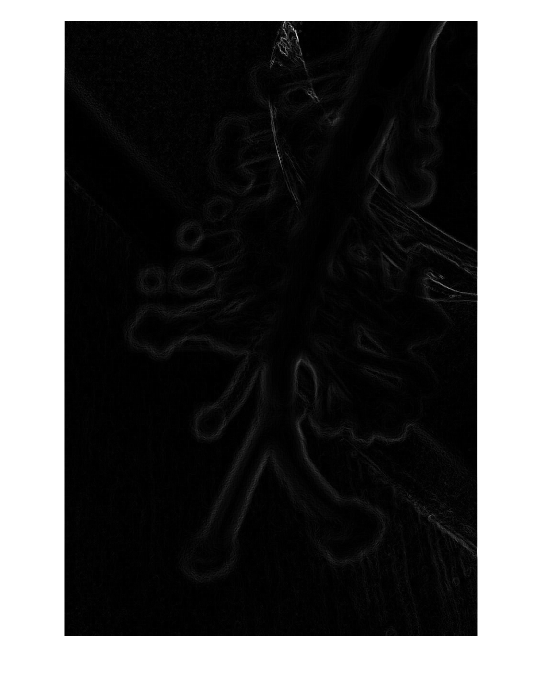

val_enfocada = sum(Modul, 'all');
% imatge enfocada
Gx = imfilter(double(F2), hx);
Gy = imfilter(double(F2), hy);
Modul = abs(Gx) + abs(Gy);
imshow(Modul,[]);

val_desenfocada = sum(Modul, 'all');
% mostrar valors
val_enfocada

val_enfocada = 35150770

val_desenfocada

val_desenfocada = 21415132

## Exercici 4.

Suavitzar una imatge per després redimensionar-la a la meitat dona un millor aspecte visual que directament redimensionar-la a la meitat. Mesureu si la relació senyal soroll millora al fer aquest procés comparant amb el de directament redimensionat sense filtrar. Per fer-ho, torneu les imatges processades a la seva mida original i calculeu el SNR.

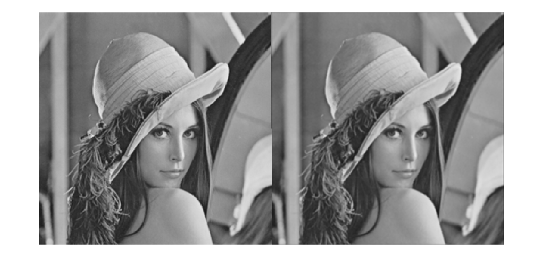

I = imread('lena_gray_512.tif');
% sense filtre
J1 = imresize(I, 0.5);
% amb filtre per mitjana
h = [1 1 1; 1 1 1; 1 1 1];
h = h/sum(h, 'all');
J2 = imfilter(I, h);
J2 = imresize(J2, 0.5);
% reescalar
K1 = imresize(J1, 2);
K2 = imresize(J2, 2);
montage({K1, K2});

% SNR sense filtre
D1 = K1 - I;
D1 = D1.*D1;
I2 = I.*I;
snr1 = sum(I2, 'all')/(sum(D1, 'all'))

snr1 = 25.5145

% SNR amb filtre per mitjana
D2 = K2 - I;
D2 = D2.*D2;
snr2 = sum(I2, 'all')/(sum(D2, 'all'))

snr2 = 18.4338